# Cell Visualization and Stats

### Required Variables

be sure to cd to the Lysosome Analysis folder

focus on 

close all
clearvars -except paths
[VL, idT, cellT, dyingT] = loadProjectTables(paths);

VL = 2032019×8 table
          Object           contour_id      x         y        z      SegmentLabel    Dataset    SizeLabel
    ___________________    __________    ______    ______    ____    ____________    _______    _________

    "TB2_TCdying-02_cw"        1         76.225    68.395    11.2         1          "TF21"         0    
    "TB2_TCdying-02_cw"        1         76.241    68.267    11.2         1          "TF21"         0    
    "TB2_TCdying-02_cw"        1         76.233    68.139    11.2         1          "TF21"         0    
    "TB2_TCdying-02_cw"        1         76.273    68.074    11.2         1          "TF21"         0    
    "TB2_TCdying-02_cw"        1         76.305     68.05    11.2     

idT = 33×8 table
               Cell                Type             Lysosome               Health      TasteBud      Source      Dataset        Folder     
    ___________________________    ____    ___________________________    _________    ________    __________    _______    _______________

    "TB1_AP16_EM"                  "I"     "TB1_AP16__LYS_RSL"            "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_AP34_EM"                  "I"     "TB1_AP34_lys_RSL"             "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_AP36_EM"                  "I"     "TB1_AP36_LYS_RSL"             "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_A

cellT = 33×8 table
               Cell                Type    Health     Volume    SurfaceArea      SAV                   Filename                 PlotSort
    ___________________________    ____    _______    ______    ___________    _______    __________________________________    ________

    "TB1_AP44_EM"                   I      early      536.17      830.87       0.64532    "TB1_AP44_EM_fx.obj"                     ed   
    "TB1_AP16_EM"                   I      healthy    490.27      737.35        0.6649    "TB1_AP16_EM_mp.obj"                     I    
    "TB1_AP34_EM"                   I      healthy    481.76         NaN           NaN    "TB1_AP34_EM_mp.obj"                     I    
    "TB1_AP36_EM"      

dyingT = 6×8 table
       Cell       Type    Health    Volume    SurfaceArea      SAV          Filename         PlotSort
    __________    ____    ______    ______    ___________    _______    _________________    ________

    "TB3_TC01"    x       late      446.93      409.98        1.0901    "TB3_TC01_mp.obj"       ld   
    "TB3_TC02"    II      early     1301.1      1608.4       0.80892    "TB3_TC02_mp.obj"       ed   
    "TB3_TC03"    III     early     1310.5      1221.4         1.073    "TB3_TC03_mp.obj"       ed   
    "TB3_TC04"    II      early       1677      1311.4        1.2788    "TB3_TC04_mp.obj"       ed   
    "TB3_TC05"    II      early     1854.5      1394.6        1.3298    "TB3_TC05_mp.obj"       

idT = sortrows(idT,["Type", "Health"])

idT = 33×8 table
               Cell                Type             Lysosome               Health      TasteBud      Source      Dataset        Folder     
    ___________________________    ____    ___________________________    _________    ________    __________    _______    _______________

    "TB1_AP44_EM"                  "I"     "TB1_AP44_LYS_RSL"             "early"       "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_AP16_EM"                  "I"     "TB1_AP16__LYS_RSL"            "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_AP34_EM"                  "I"     "TB1_AP34_lys_RSL"             "healthy"     "TB1"      "Rob"         "TF21"     "ROB_TF21_TB1" 
    "TB1_A

### Merge Cell Volumes

T = [cellT; dyingT];
T = sortrows(T,["Type","Volume"]);

1. TB1_AP37_EM. healthy. 392.01
2. TB1_AP38_EM. healthy. 407.79
3. TB1_AP36_EM. healthy. 472.18
4. TB1_AP34_EM. healthy. 481.76
5. TB1_AP16_EM. healthy. 490.27
6. TB1_AP44_EM. early. 536.17
7. TB2 Nucleus_04_cw_cell-ry. healthy. 690.62
8. TB1_AP70_RSL. healthy. 866.79
9. TB2_T1C-06_cw. healthy. 1212.88
10. TB2_T1C-05_cw. healthy. 1637.33


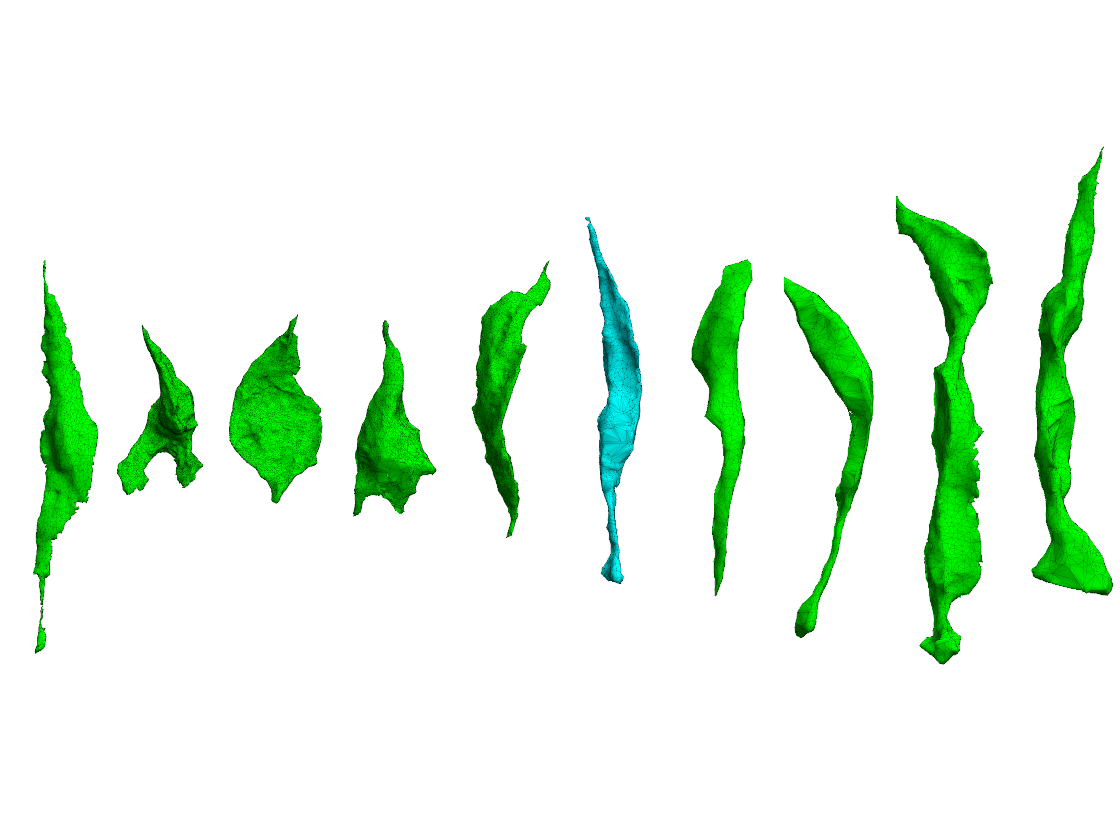

display_cell_by_type(T, "I")

11. TB2_T2C-12_cw. healthy. 810.93
12. TB1_AP14_EM. healthy. 951.12
13. TB2_T2Cell03_CM_LES. healthy. 988.13
14. TB2_T2C-09_cw. healthy. 1054.02
15. TB1_AP51_EM. early. 1066.87
16. TB2_T2C-10_cw. healthy. 1173.65
17. TB3_TC02. early. 1301.09
18. TB1_AP40_EM. early. 1398.27
19. TB2_T2C-03_cw. early. 1408.91
20. TB1_AP13_EM. early. 1543.46
21. TB3_TC04. early. 1677.04
22. TB3_TC05. early. 1854.52
23. TB2_T2C-01_FR. early. 1984.42


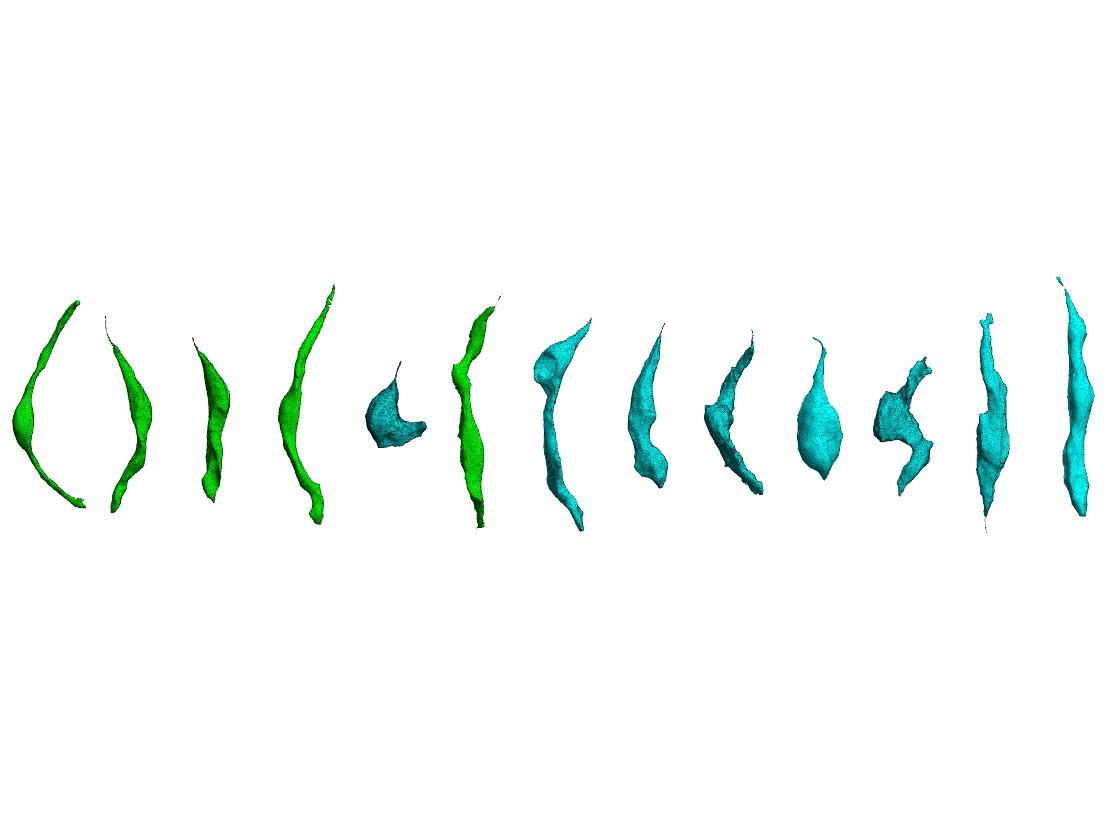

display_cell_by_type(T,"II")

23. TB2_t3cell02_CM_RSL. healthy. 524.77
24. TB1_AP31_EM. healthy. 560.82
25. TB2_T3Cell07_cm_RSL. healthy. 577.43
26. TB2_T3C-17_cw. healthy. 616.43
27. TB2_T3C-08_cw. healthy. 663.79
28. TB1_AP02_EM. healthy. 674.29
29. TB2_T3C-14_FR. healthy. 810.45
30. TB3_TC06. early. 1219.70
31. TB3_TC03. early. 1310.51


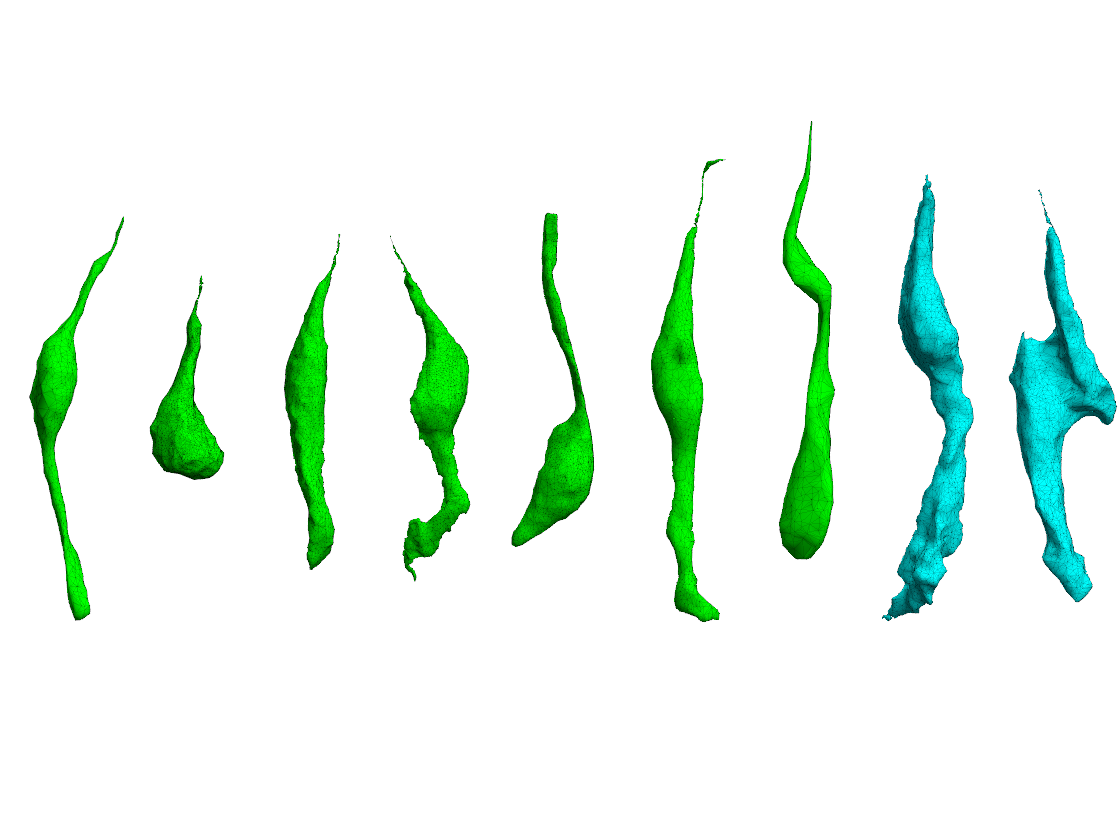

display_cell_by_type(T,"III")

32. TB1_IMMcell08_CM_RKJ. healthy. 191.43
33. TB1_IMMCell09_CM_ry. healthy. 350.13
34. TB2 Nucleus_26_cw_IV-ry. healthy. 550.18
35. TB2_T4C-01_cw. healthy. 742.60


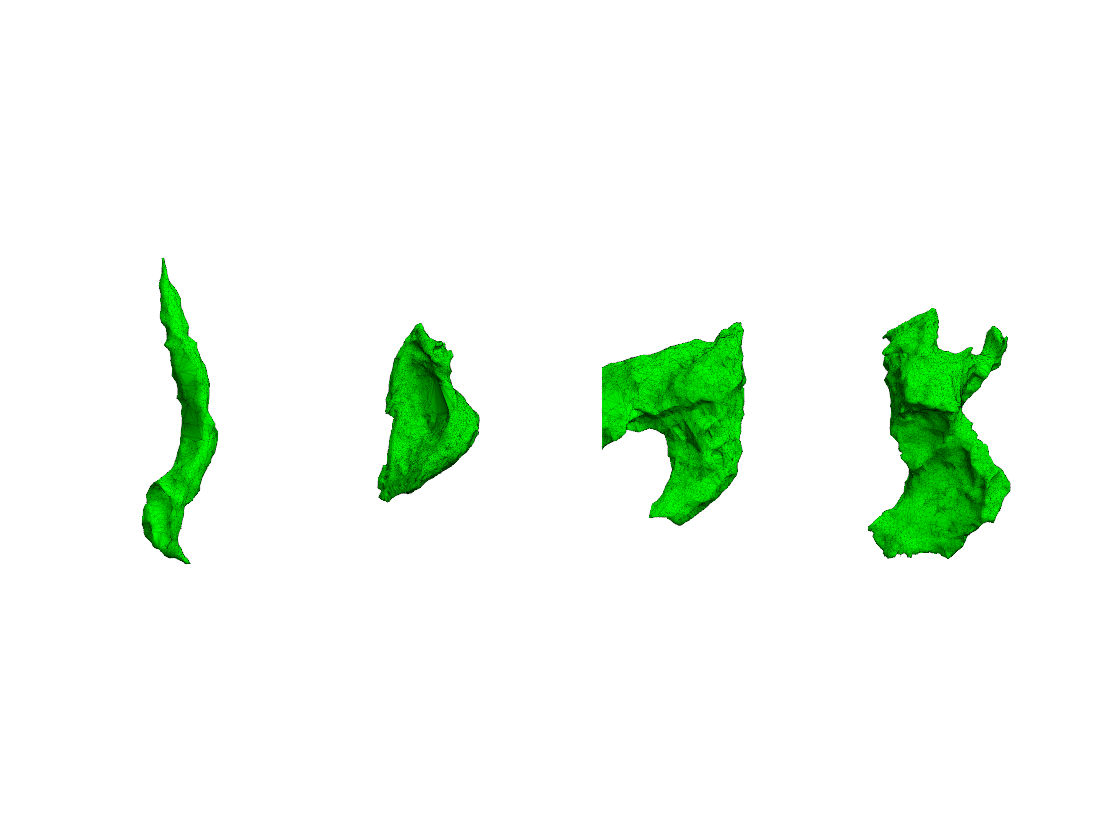

display_cell_by_type(T,"IV")

37. TB2_TCdying01. late. 403.60
38. TB3_TC01. late. 446.93
39. TB2_TCdying02. late. 457.08


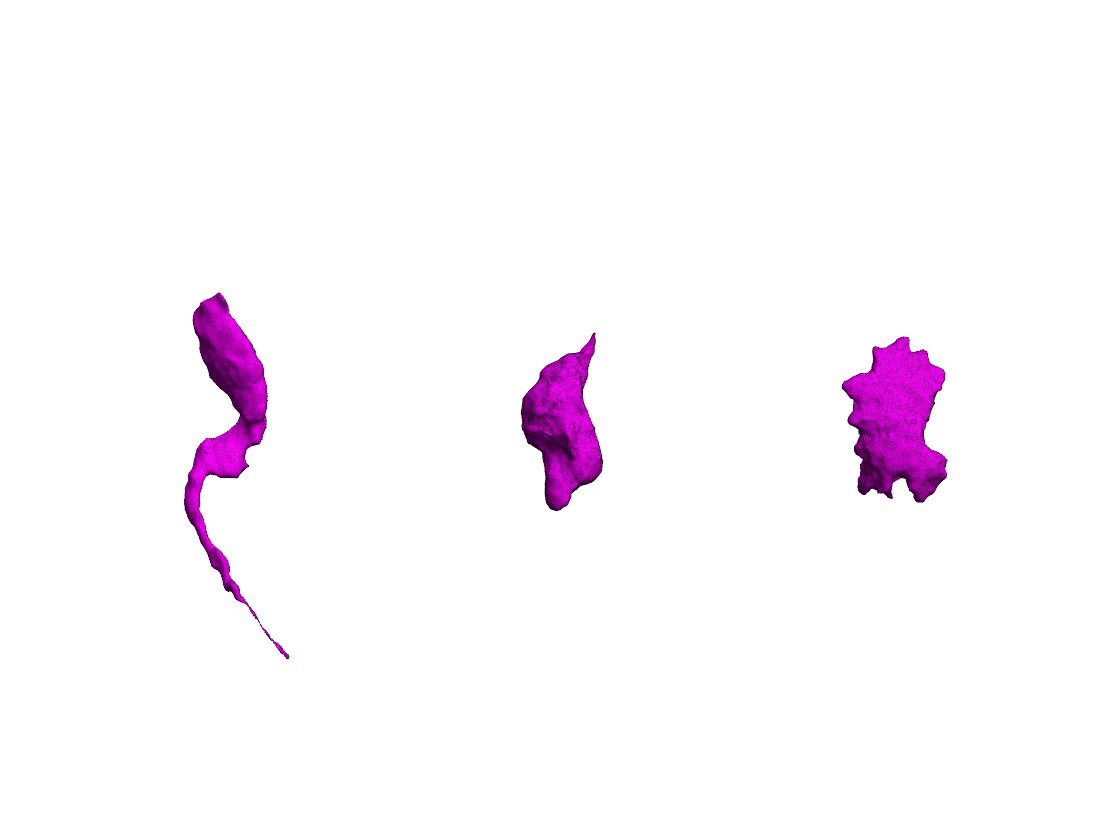

display_cell_by_type(T,"x")

early dying here is a type II cell

writetable(T,"cell_metrics.csv")

## Statistics

mmSetFigPublication

Default figure color set to white.
Default font size set to 16.0.

### Volume of Cell by Type

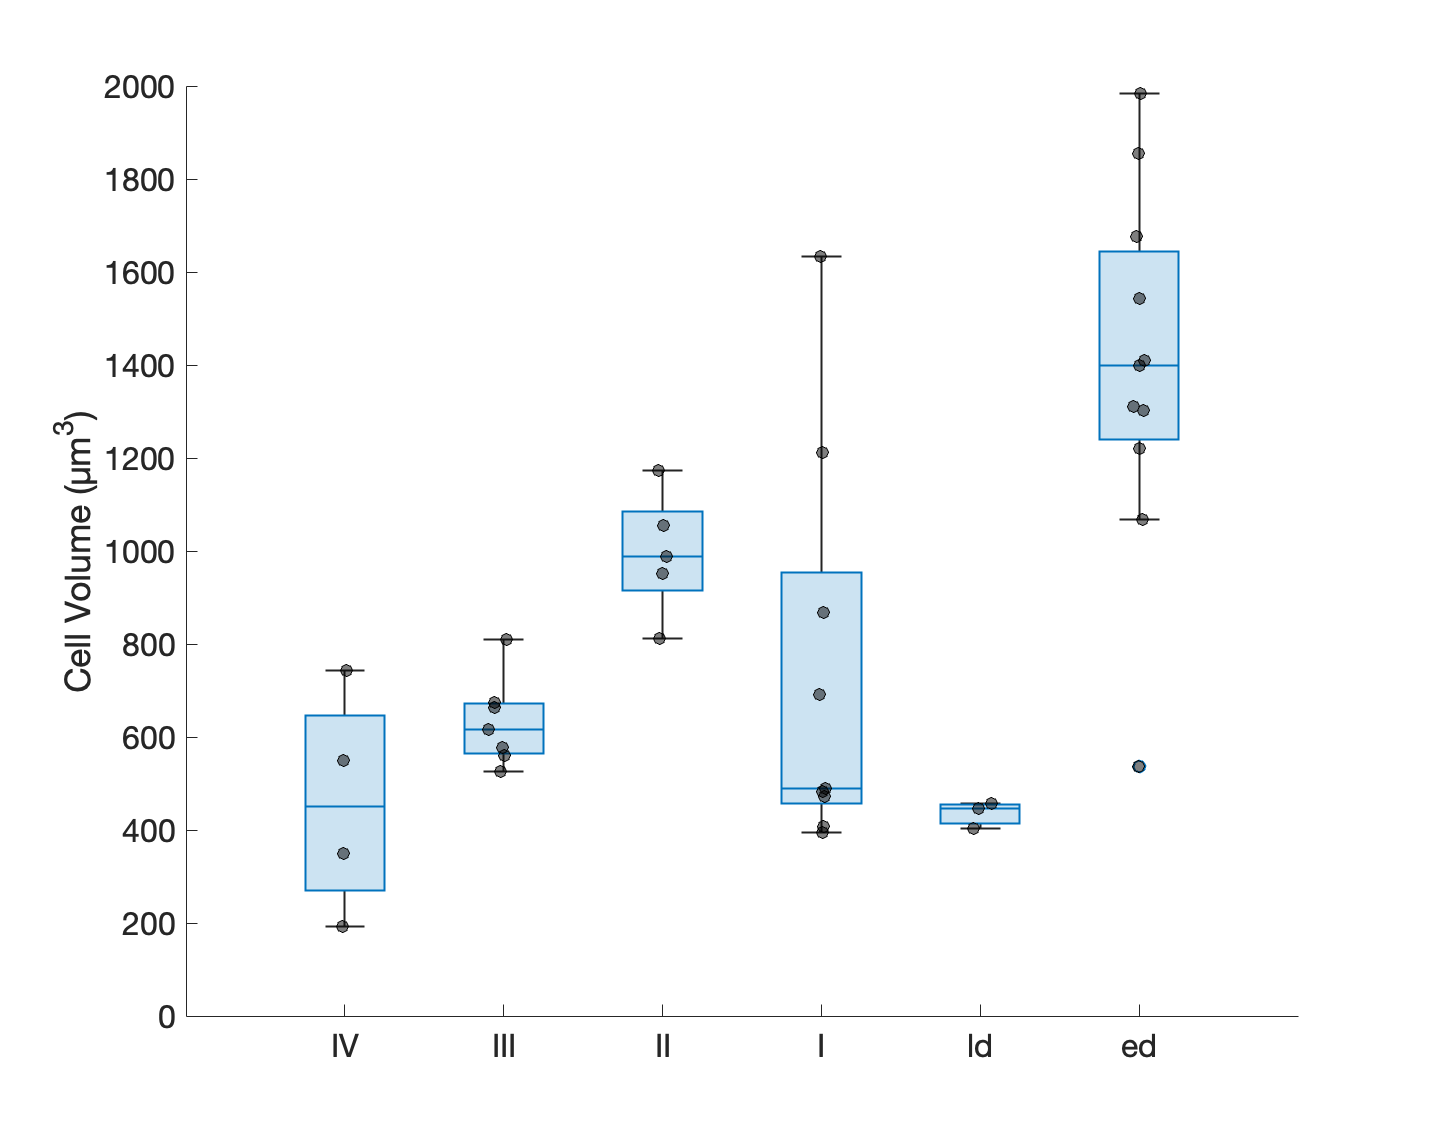

mmfig;

tiledlayout("horizontal")

g = T.PlotSort;
y = T.Volume;

hold on
boxchart(g,y,BoxFaceColor="#0072BD",Notch="off")
swarmchart(g,y, ...
    MarkerFaceColor="k", ...
    MarkerFaceAlpha=0.5, ...
    MarkerEdgeColor="k", ...
    XJitterWidth=0.25)
ylabel('Cell Volume (µm^3)')

### Volume of Cell by Type, Grouped by Health

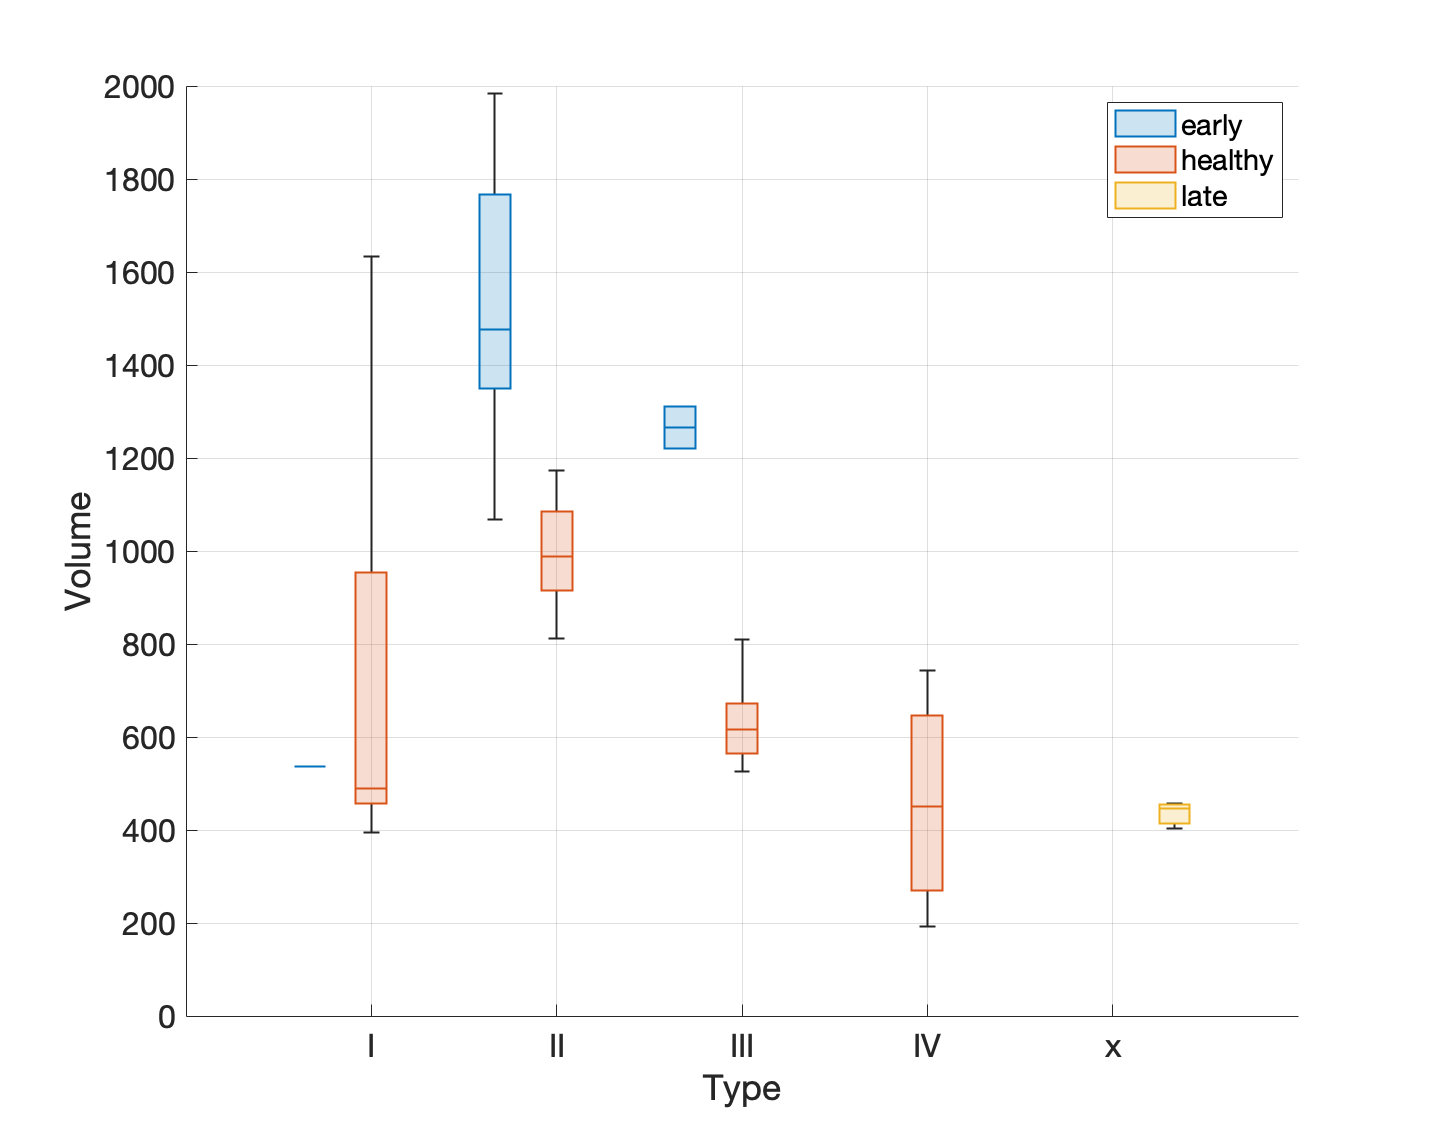

mmfig;
boxchart(T.Type,T.Volume,GroupByColor=T.Health)
legend
grid on
xlabel('Type'); ylabel('Volume')

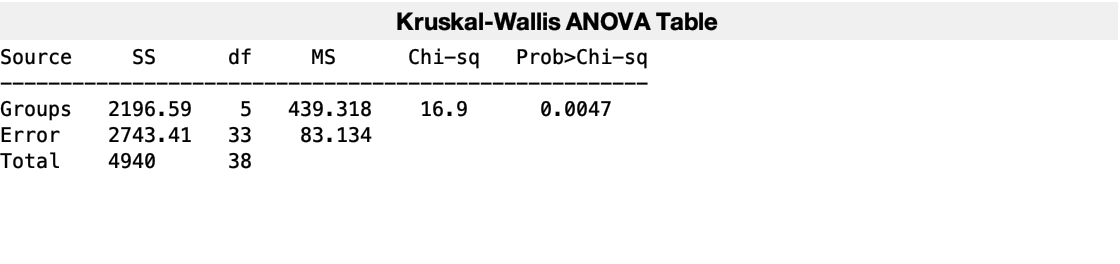

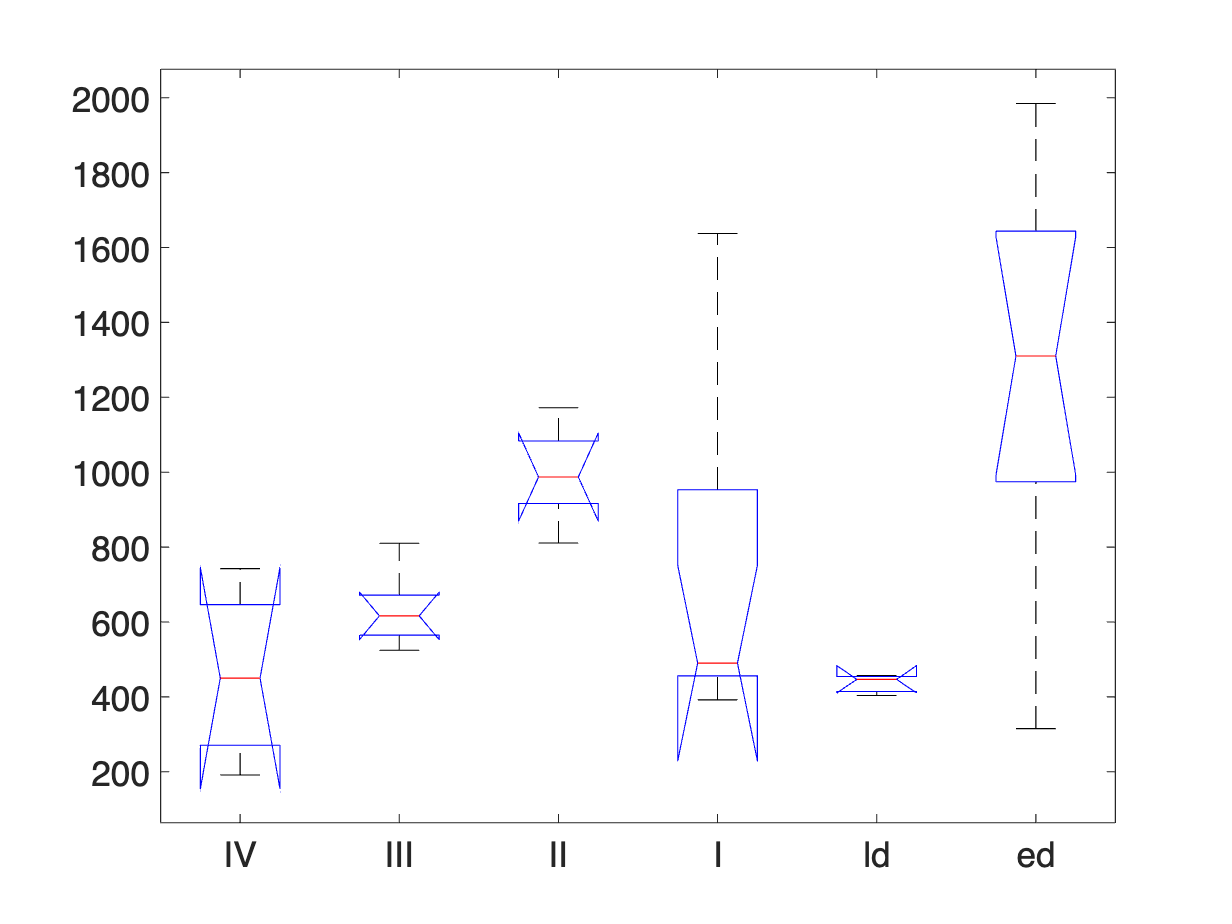

p =     0.0046996


tbl = 4×6 cell array
    {'Source'}    {'SS'    }    {'df'}    {'MS'      }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[2196.6]}    {[ 5]}    {[  439.32]}    {[  16.897]}    {[  0.0046996]}
    {'Error' }    {[2743.4]}    {[33]}    {[  83.134]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[  4940]}    {[38]}    {0×0 double}    {0×0 double}    {0×0 double   }


stats = struct with fields:
       gnames: {6×1 cell}
            n: [4 7 5 9 3 11]
       source: 'kruskalwallis'
    meanranks: [9.75 17 26.8 16.778 6.6667 28.818]
         sumt: 0


[p,tbl,stats]=kruskalwallis(y,g)

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


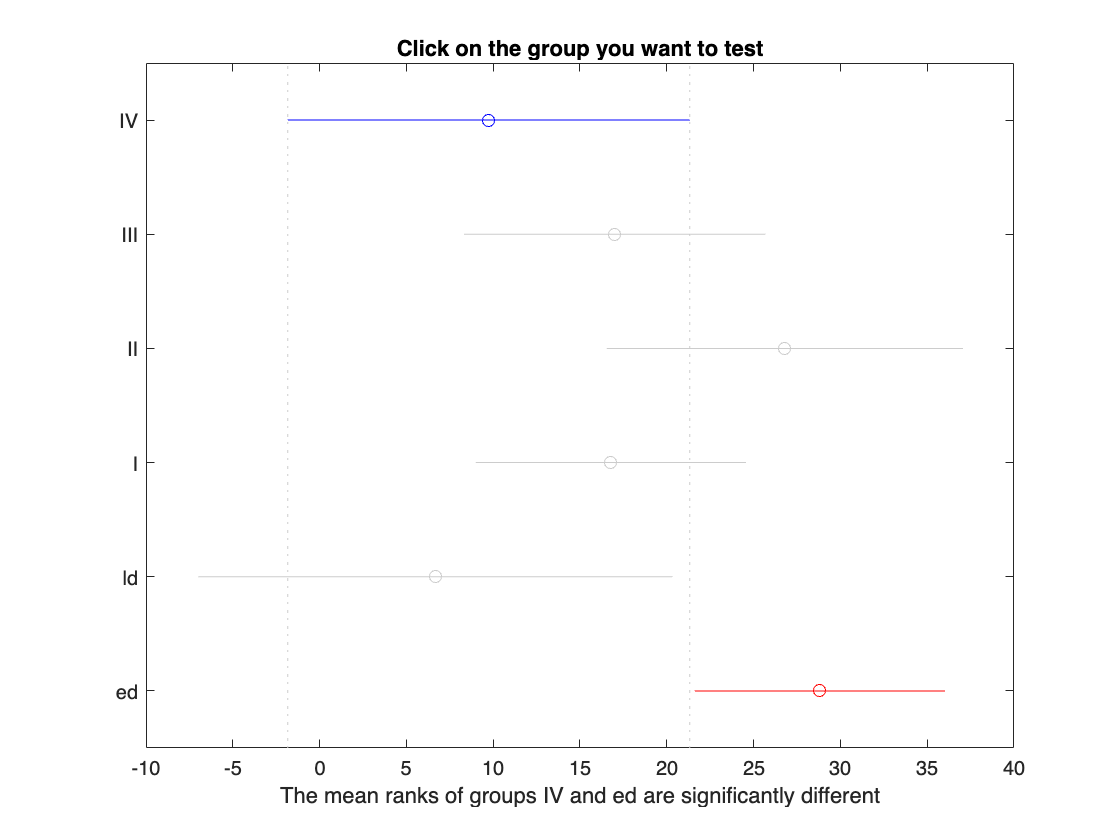

c = multcompare(stats);

## Local Functions

function display_cell_by_type(T,type)

arguments
    T table % cellT or dyingT
    type {mustBeText}
end


la = T.Type == type;
count = nnz(la);
idc = find(la)';
colorD = dictionary(["healthy" "early" "late"], ["g" "c" "m"]);

meshFolder = T.Properties.UserData.meshPath;

figure(Visible='on',Color='w')
tiledlayout(1,count,"TileSpacing","none","Padding","tight")
for n=idc
    
    fullpath = fullfile(meshFolder, T.Filename(n));
    cellName = T.Cell(n);

        mesh = readSurfaceMesh(fullpath);
        nexttile
        
        plotCellMesh(mesh,colorD(T.Health(n)))

        % simplify(mesh);
        %  % simplify(mesh,SimplificationMethod="quadric-decimation")
        %  % simplify(mesh,SimplificationMethod="vertex-clustering")
        % 
        % 
        % patch(Faces=mesh.Faces,Vertices=mesh.Vertices, ...
        %     FaceColor=colorD(T.Health(n)), ...
        %     edgeAlpha = 0.1)
        % axis equal off
        % xlim([-10 10])
        % ylim([-10 10])
        % zlim([-50 50])
        % 
        % set(gca,CameraTarget=[0,0,0])
        % view([0 0])
        % 
        % % lightangle(45,30);
        % lighting gouraud
        % material dull
        % 
        % % camera position - adds two opposing lights for better visibility
        % camlight('right')
        % camorbit(180,0,'data',[0 0 1])
        % camlight('right')

        fprintf('%d. %s. %s. %1.2f\n', n, cellName, T.Health(n), T.Volume(n))
    % catch
    %     fprintf('%d. %s did not print.\n',n,cellName)
    % end

end
end

function display_surfaceMesh(paths, cell)
    fullpath = fullfile(paths.cellMesh,cell+"_manifold.obj");
    mesh = readSurfaceMesh(fullpath);
    surfaceMeshShow(mesh)
end
